## **ASSIGNMENT 2 -- DECODING NEURAL ACTIVITY**

Federico Stella (f.stella@donders.ru.nl)

In this notebook we will take a look at some tecniques aimed at "reading" neural activity and allowing us to interpret its content and to evaluate how much information it carries about a specific set of stimuli, conditions or states. 

This LiveScript MATLAB environemt is very similar to the Jupyter notebook you used in the previous assignment. Differently from Python, we do not need to prepare any environment, you can run the code in this script straight away from any Matlab application. 

You can complete the assignements directly in this notebook or copy any part of the code in anotheratlab LiveScript, another regular script or run it directly from the Command Window. Using a LiveScript like this allows you to insert text, comments or observations, you just need to use the "Text" and "Code" commands at the top to switch between the two modes. 

## **DECODING ON A LINEAR TRACK**

The main aim of this assignment is to familiarize you with the concept of decoding of neural activty. The idea is that if certain neurons are consistently active whenever a stimulus is present, then by oberving at a later time the same neural activity, we can predict the presence of that stimulus, or more generrally argue that the network is currently expressing the neural representation of that stimulus. For more details about decoding you can read this 

In the context of the hippocampus and of place cells, the different positions that an animal can occupy in an environment provide the set of external stimuli that is represented in the activity of the cells. Therefore in the following we will see how recording activity from a set of place cells allows us to reconstruct the current position of the animal with some degree of accuracy. 

**Simulated Place Cells** 

We first generate a place field map to provide a neural representation of the linear environment, much like you have already seen in the previous assignment.  We simulate spike trains as inhomogeneous Poisson processes, with a rate determined by the current animal position. An inhomogeneous Poisson process is a random process where the instantaneous probability to have an event at time  (more precisely, the probability of having an event between times t and t+dt  is given by: 


$$P(event in[t, t+dt]=\lambda(t)dt$$


## Place Field Properties

clear all
track_length = 200; % the length of our linear track (eg in centimeter)
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 100; % how many cells we are recording
pf_centers = rand(n_cells,1) * track_length; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
pf_size = gamrnd(10,1, n_cells,1); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,1); % the peak firing rate for each cell, drawn from an exponential distribution

## Build the place field representation 

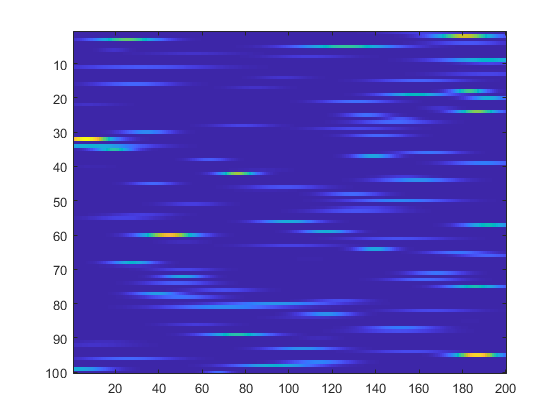

bins=1:track_length;
true_firing_rate=zeros(n_cells,track_length);
%Place Fields have a Gaussian shape
for i=1:n_cells
    true_firing_rate(i,:)=pf_rate(i).*exp(-(bins-pf_centers(i)).^2/(2*pf_size(i)^2));
end

imagesc(true_firing_rate)

## Generate a random trajectory on the track 

Let's simulate the trajectory of the virtual mouse on the track. As we are only interested in the periods during which the animal is moving, we will omit the pauses at tehe two ends of the track. The trajectory will therefore consits of laps directly alternating between the two running directions. 

n_runs = 20; 
av_running_speed = 10;% the average running speed (in cm/s)
fps = 10; % the number of "video frames" per second 
running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
running_speed_b = chi2rnd(av_running_speed, n_runs,1); 

x = [];
for i=1:n_runs
    run_length = numel(bins) * fps / running_speed_a(i);
    run1 = linspace(0.1, numel(bins), round(run_length));
    run_length = numel(bins) * fps / running_speed_b(i);
    run2 = linspace(numel(bins), 0.1, round(run_length));
    x=cat(1,x,run1(:),run2(:));
end
t=(1:numel(x))./fps; 


## Generate spikes for cells

Combining the rate maps and the trajectory generated above we can now simulate the spiking activity of our neural population.

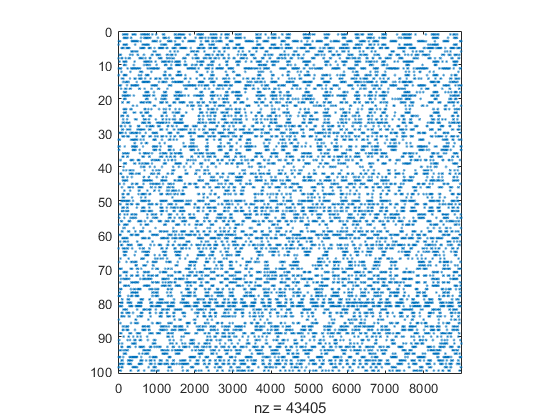

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 0.1; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
end

spy(spikes)
axis square

## Reconstruct place-related activity from sampled activity

We are now ready to proceed with the first step towards decoding of position. We will start by looking at how different locations are encoded by the neurons. To do that we will collect all the activity emitted by the neurons in a specific location and average it to obtain a Population Vector (PV) associated to that position, or equivalently we will say that the firing rate combination of this PV represent that location. Since we will do this for every location in the environment we will end up having the PVs associated to every portion of the environment. 

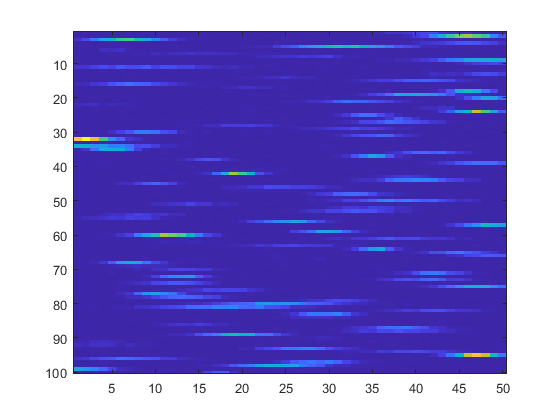

% To estimate the PVs we will use bins of some cms in length 
bin_size=4; % Size in cm of bins to use for encoding
n_bins = track_length/bin_size;

estim_firing_rate=zeros(n_cells,n_bins);

% Rescale the trajectory to the new binning 
x_sampling_binned = ceil(x_sampling/(track_length/n_bins));

% Calculate the PV for every bin
for j=1:n_bins
    X_bin=find(x_sampling_binned==j);
    estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
end

imagesc(estim_firing_rate)

imagesc(true_firing_rate)

Since the spikes we are using to estimate the track representation are a finite sample of the '"ground-truth" maps, and moreover we have added random noise in the process, the reconstructed maps will not be identical to the original ones. Actually, they can be quite different, especially in real experiments where the amount of data is limited, the behaviour of the animal is not completely controlled, neural activity is subject to high level of noise, and obviously we don't have access to the "ground-truth". 

**Question 1: **In the context of the simulated data, one can look at the effects of data amount and level of noise on the accuracy of the PV estimation. Build a table expressing the relationship between noise level, amount of recorded runs and the difference between the real and the reconstructed maps.

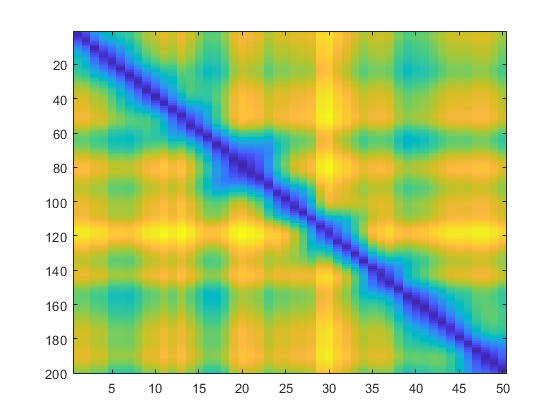

% We can evaluate the difference using euclidean distance, for example 
DD=pdist2(true_firing_rate',estim_firing_rate','euclidean');
imagesc(DD)

Estim_Accuracy = min(DD,[],1);

Okay, so let's change some values around and create a table! We'll do a loop over both data amount ant noise level and subsequently look at the average accuracy for all bins.

runs = [10,20,50,75,100]; %This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
noise_firing_rates = [0.1,0.5,1,5,10]; % the baseline noise firing rate

it = 1;
for k = 1:numel(noise_firing_rates)
    noise_firing_rate = noise_firing_rates(k);
    for l = 1:numel(runs)
        n_runs = runs(l);
        
        running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
        running_speed_b = chi2rnd(av_running_speed, n_runs,1); 
        
        x = [];
        for i=1:n_runs
            run_length = numel(bins) * fps / running_speed_a(i);
            run1 = linspace(0.1, numel(bins), round(run_length));
            run_length = numel(bins) * fps / running_speed_b(i);
            run2 = linspace(numel(bins), 0.1, round(run_length));
            x=cat(1,x,run1(:),run2(:));
        end
        t=(1:numel(x))./fps; 
        
        t_sampling = (1:numel(t))./sampling_rate;
        x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
        
        spikes = zeros(n_cells,numel(t_sampling));
        
        for i=1:n_cells
            inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
            inst_rate(inst_rate<0) = 0;
            spikes_loc = poissrnd(inst_rate/sampling_rate);
            spikes(i,:)=spikes_loc;
        end
        estim_firing_rate=zeros(n_cells,n_bins);
        % Rescale the trajectory to the new binning 
        x_sampling_binned = ceil(x_sampling/(track_length/n_bins));
        
        % Calculate the PV for every bin
        for j=1:n_bins
            X_bin=find(x_sampling_binned==j);
            estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
        end
        
        % We can evaluate the difference using euclidean distance, for example 
        DD=pdist2(true_firing_rate',estim_firing_rate','euclidean');
        Estim_Accuracy = min(DD,[],1);
        avg_estim_accuracy = mean(Estim_Accuracy);

        % Save statistics
        accuracies(it) = avg_estim_accuracy;
        noise_(it) = noise_firing_rate;
        runs_(it) = n_runs;
        it = it + 1;
    end
end

tab = table(runs_(:),noise_(:),accuracies(:),'VariableNames',{'Runs','Noise','Error'})

tab = 25×3 table
    Runs    Noise    Error 
    ____    _____    ______

     10      0.1      2.409
     20      0.1     1.8551
     50      0.1     1.2046
     75      0.1     1.0854
    100      0.1     1.0178
     10      0.5     3.1693
     20      0.5     2.6382
     50      0.5     2.2113
     75      0.5     2.0841
    100      0.5     2.0259
     10        1     4.5734
     20        1     4.1419
     50        1     3.7841
     75        1       3.77
    100        1     3.7319
     10        5     19.268


So we see that our error goes up if we have more noise in our data, this is of course very straight forward. Additionally, and equally logical, our error goes down if we increase the amount of runs and therefore our amount of data, this error is still very much dictated by the noise, however. If we have noisy data, we can essentially do as many runs as we'd like but still not get very far, this is due to the fact that we have a very large variance in our data at such high noise levels.

**BAYESIAN DECODING**

Now that we have estimated the PVs associated to the track environment, we can move on to decoding. 

A very common approach is given by the so called Bayesian Decoding ([Quiroga](https://www.nature.com/articles/nrn2578) and [Pouget](https://www.nature.com/articles/35039062) for a review on the topic). Let *P(s)* denote the probability of presentation of stimulus *s* (belonging to a set *S*) and *P (r|s)* denote the conditional probability of obtaining a population response *r* (out of a response set *R*) when stimulus *s* is presented. Using Bayes' theorem, we obtain:


$$P(s|r)=\frac{P(r|s)*P(s)}{P(r)}$$


This equation gives the posterior probability that, given a response *r*, stimulus *s* was presented. Bayesian decoding calculates from this posterior probability distribution a single prediction of the most likely stimulus 


$$s^*=argmax_s(P(s|r))$$


In our case the set of stimuli *S *are the different locations in the environment. Since we are looking for the maximum, we can ignore the denominator term P(r), as it is common to all positions *s *(luckily for us, as it is generally very difficult to estimate experimentally)*. *Moreover we will assume that every position s is equiprobable, so we can also ignore the term P(s). Assuming that our neurons are independant (a banality in our simulations, but not necessarily true when considering real neurons), we are left with: 


$$s^*= argmax_s(\prod_iP(r_i|s))$$


And here is the code to perform bayesian decoding: 

% First we again need to get some nice data because we messed with it in our previous
% section to test on noise and data size

n_runs = 20;
av_running_speed = 10;% the average running speed (in cm/s)
fps = 10; % the number of "video frames" per second 
running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
running_speed_b = chi2rnd(av_running_speed, n_runs,1); 

x = [];
for i=1:n_runs
    run_length = numel(bins) * fps / running_speed_a(i);
    run1 = linspace(0.1, numel(bins), round(run_length));
    run_length = numel(bins) * fps / running_speed_b(i);
    run2 = linspace(numel(bins), 0.1, round(run_length));
    x=cat(1,x,run1(:),run2(:));
end
t=(1:numel(x))./fps; 

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 0.1; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
end

% To estimate the PVs we will use bins of some cms in length 
bin_size=10; % Size in cm of bins to use for encoding
n_bins = track_length/bin_size;

estim_firing_rate=zeros(n_cells,n_bins);

% Rescale the trajectory to the new binning
x_sampling_binned = ceil(x_sampling/(track_length/n_bins));

% Calculate the PV for every bin
for j=1:n_bins
    X_bin=find(x_sampling_binned==j);
    estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
end

x_decoded=zeros(size(spikes,2),1);
for t_bin=1:size(spikes,2)
    
    if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
    
    Post_p=NaN(size(estim_firing_rate,2),1);
    for i=1:size(estim_firing_rate,2)
        % Note that we work with log so that we can sum probabilities
        % instead of multiplying them 
        Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate(:,i)/sampling_rate)));
    end
    x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
    else
    x_decoded(t_bin) = NaN;
    end
end

**Question 2: **What is the reason for calculating a log-probability instead a probability? 

Calculating with bayesian mathematics becomes a lot easier when we consider log-probabilities instead of just probabilities. This is mainly due to the fact that we can write log(p1(x)*p2(x)) = log(p1(x)) + log(p2(x)). We can thus write our multiplications with sums if we consider log-space, this makes it of course way easier to work with our probabilities and also increases computational speeds (addition is computationally less expensive than multiplication).

In addition, we may work with exponential functions if we, for example, consider a normal distribution. In this case, the exponents also directly come into the log-space making it easier to work with since they don't have their nasty exponents anymore.

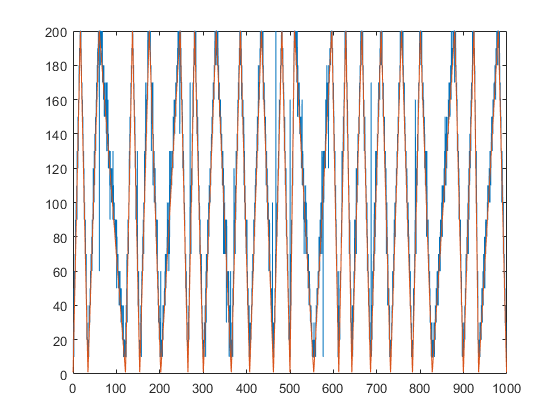

%Plot the real trajectory agains the reconstructed one
plot(t_sampling,x_decoded*bin_size,t_sampling,x_sampling)

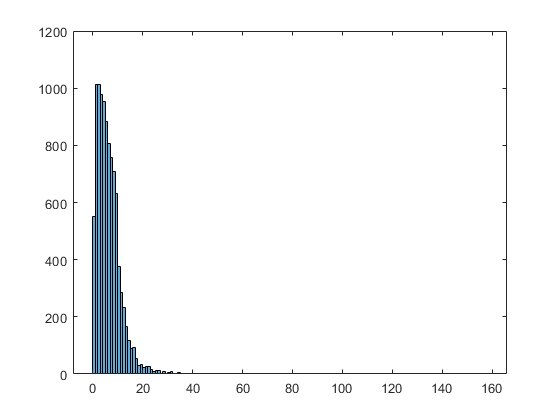


%Distribution of errors
histogram(sqrt(((x_sampling-x_decoded*bin_size).^2)))


%To reduce the effects of the few large errors, the median error, rather
%than the mean error, is a commonly used measure of decoding precision
nanmedian(sqrt(((x_sampling-x_decoded*bin_size).^2)))

ans = 5

**Question 3: **how much data is required to reduce the median error? Use smaller fractions of data to estimate PVs and measure how this affects the decoding error.

Okay so let's first see what our median error becomes for different amounts of data and make a plot.

runs = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16];
meds = 0:numel(runs)-1;

for it = 1:numel(runs)
    n_runs = runs(it)
    running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
    running_speed_b = chi2rnd(av_running_speed, n_runs,1);
    
    x = [];
    for i=1:n_runs
        run_length = numel(bins) * fps / running_speed_a(i);
        run1 = linspace(0.1, numel(bins), round(run_length));
        run_length = numel(bins) * fps / running_speed_b(i);
        run2 = linspace(numel(bins), 0.1, round(run_length));
        x=cat(1,x,run1(:),run2(:));
    end
    t=(1:numel(x))./fps; 
    
    sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
    t_sampling = (1:numel(t))./sampling_rate;
    x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
    noise_firing_rate = 5; % the baseline noise firing rate
    
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,:)=spikes_loc;
    end
    
    % To estimate the PVs we will use bins of some cms in length 
    bin_size=20; % Size in cm of bins to use for encoding
    n_bins = track_length/bin_size;
    
    estim_firing_rate=zeros(n_cells,n_bins);
    
    % Rescale the trajectory to the new binning 
    x_sampling_binned = ceil(x_sampling/(track_length/n_bins));
    
    % Calculate the PV for every bin
    for j=1:n_bins
        X_bin=find(x_sampling_binned==j);
        estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
    end
    
    running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
    running_speed_b = chi2rnd(av_running_speed, n_runs,1);
    
    x = [];
    for i=1:n_runs
        run_length = numel(bins) * fps / running_speed_a(i);
        run1 = linspace(0.1, numel(bins), round(run_length));
        run_length = numel(bins) * fps / running_speed_b(i);
        run2 = linspace(numel(bins), 0.1, round(run_length));
        x=cat(1,x,run1(:),run2(:));
    end
    t=(1:numel(x))./fps; 
    
    sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
    t_sampling = (1:numel(t))./sampling_rate;
    x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
    noise_firing_rate = 5; % the baseline noise firing rate
    
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,:)=spikes_loc;
    end
    
    x_decoded=zeros(size(spikes,2),1);
    for t_bin=1:size(spikes,2)
        
        if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
        
        Post_p=NaN(size(estim_firing_rate,2),1);
        for i=1:size(estim_firing_rate,2)
            % Note that we work with log so that we can sum probabilities
            % instead of multiplying them 
            Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate(:,i)/sampling_rate)));
        end
        x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
        else
        x_decoded(t_bin) = NaN;
        end
    end
    meds(it) = nanmedian(sqrt(((x_sampling-x_decoded*bin_size).^2)));
end

n_runs = 1

n_runs = 2

n_runs = 3

n_runs = 4

n_runs = 5

n_runs = 6

n_runs = 7

n_runs = 8

n_runs = 9

n_runs = 10

n_runs = 11

n_runs = 12

n_runs = 13

n_runs = 14

n_runs = 15

n_runs = 16

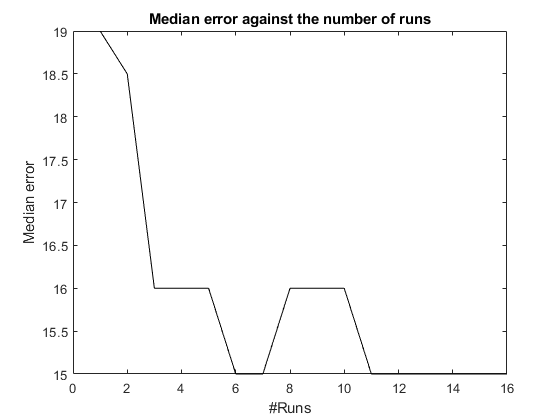

plot(runs, meds,'k')
xlabel('#Runs')
ylabel('Median error')
title('Median error against the number of runs')

So we see, with a noise of 1, we need about 12 runs in order to reach the asymptot of our median error. Smaller fractions of data will make our error increase, while more data makes our error decrease. This is of course logical as more data would mean we are better able to decode the signal overall.

**Question 4: **how does the reconstruction error scales with the number of available place cells? Having many cells representing an environment allows for more information to be found in the same time window and reduces the effect of random noise. But how many place cells would be requied on average to accurately represent position on a linear track? Quantify the average decoding error obtainable with different population sizes and find for what value it reaches its asymptot. 

cells = 5:10:100;
meds = 0

meds = 0

n_runs = 5;

for it = 1:numel(cells)
    n_cells = cells(it);
    bins=1:track_length;
    true_firing_rate=zeros(n_cells,track_length);
    %Place Fields have a Gaussian shape
    for i=1:n_cells
        true_firing_rate(i,:)=pf_rate(i).*exp(-(bins-pf_centers(i)).^2/(2*pf_size(i)^2));
    end
    
    running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
    running_speed_b = chi2rnd(av_running_speed, n_runs,1); 
    
    x = [];
    for i=1:n_runs
        run_length = numel(bins) * fps / running_speed_a(i);
        run1 = linspace(0.1, numel(bins), round(run_length));
        run_length = numel(bins) * fps / running_speed_b(i);
        run2 = linspace(numel(bins), 0.1, round(run_length));
        x=cat(1,x,run1(:),run2(:));
    end
    t=(1:numel(x))./fps; 
    
    sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
    t_sampling = (1:numel(t))./sampling_rate;
    x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
    noise_firing_rate = 0.5; % the baseline noise firing rate
    
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,:)=spikes_loc;
    end
    
    % To estimate the PVs we will use bins of some cms in length 
    bin_size=10; % Size in cm of bins to use for encoding
    n_bins = track_length/bin_size;
    
    estim_firing_rate=zeros(n_cells,n_bins);
    
    % Rescale the trajectory to the new binning 
    x_sampling_binned = ceil(x_sampling/(track_length/n_bins));
    
    % Calculate the PV for every bin
    for j=1:n_bins
        X_bin=find(x_sampling_binned==j);
        estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
    end
    
    sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
    t_sampling = (1:numel(t))./sampling_rate;
    x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
    noise_firing_rate = 0.5; % the baseline noise firing rate
    
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,:)=spikes_loc;
    end
    
    x_decoded=zeros(size(spikes,2),1);
    for t_bin=1:size(spikes,2)
        
        if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
        
        Post_p=NaN(size(estim_firing_rate,2),1);
        for i=1:size(estim_firing_rate,2)
            % Note that we work with log so that we can sum probabilities
            % instead of multiplying them 
            Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate(:,i)/sampling_rate)));
        end
        x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
        else
        x_decoded(t_bin) = NaN;
        end
    end
    meds(it) = nanmedian(sqrt(((x_sampling-x_decoded*bin_size).^2)));
end

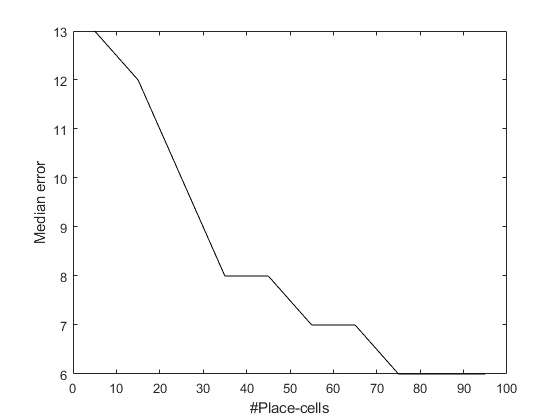

plot(cells, meds,'k')
xlabel('#Place-cells')
ylabel('Median error')

We took a noise value of 0.5 in this simulation. We see that our decoding error still goes down up to about 75 place-cells, afterwards the error seems to be reaching its asymptot of a median error of around 6. This means that if we add more cells than around 75, we do not gain any more information than we already have (or at least very little more).

**Question 5: **Bayesian decoding is not the only available option ([Abbott](https://www.cambridge.org/core/journals/quarterly-reviews-of-biophysics/article/decoding-neuronal-firing-and-modelling-neural-networks/B6387621EFFDFCF5ADE95C965A31D919)). Another possibility is to directly compare the activity present in a given time window with all PVs and find which one is the more "similar" (then the associated position would be the decoded one). As a definition of similarity one can use euclidean distance, correlation, cosine distance. Compare the performance of different decoding approaches. For example use Bayesian and correlation-based decoding.

% You can use the pdist2 built-in function to explore different similarity
% measures. Here I am comparing the PV for bin i to the activity at time t
pdist2(estim_firing_rate(:,i)',spikes(:,t_bin)','cosine');

% First we again need to set everything up accordingly

n_cells = 50; % Let's take 50 cells since we know this is decent for our purposes from previous exercise
bins=1:track_length;
true_firing_rate=zeros(n_cells,track_length);
%Place Fields have a Gaussian shape
for i=1:n_cells
    true_firing_rate(i,:)=pf_rate(i).*exp(-(bins-pf_centers(i)).^2/(2*pf_size(i)^2));
end

running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
running_speed_b = chi2rnd(av_running_speed, n_runs,1); 

x = [];
for i=1:n_runs
    run_length = numel(bins) * fps / running_speed_a(i);
    run1 = linspace(0.1, numel(bins), round(run_length));
    run_length = numel(bins) * fps / running_speed_b(i);
    run2 = linspace(numel(bins), 0.1, round(run_length));
    x=cat(1,x,run1(:),run2(:));
end
t=(1:numel(x))./fps; 

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 5; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
end

% To estimate the PVs we will use bins of some cms in length 
bin_size=10; % Size in cm of bins to use for encoding
n_bins = track_length/bin_size;

estim_firing_rate=zeros(n_cells,n_bins);

% Rescale the trajectory to the new binning 
x_sampling_binned = ceil(x_sampling/(track_length/n_bins));

% Calculate the PV for every bin
for j=1:n_bins
    X_bin=find(x_sampling_binned==j);
    estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
end

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 5; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
end

x_decoded_bay=zeros(size(spikes,2),1);
x_decoded_euc=zeros(size(spikes,2),1);
x_decoded_cor=zeros(size(spikes,2),1);
x_decoded_cos=zeros(size(spikes,2),1);
for t_bin=1:size(spikes,2)
    if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
        Post_p=NaN(size(estim_firing_rate,2),1);
        euc=NaN(size(estim_firing_rate,2),1);
        cor=NaN(size(estim_firing_rate,2),1);
        cos=NaN(size(estim_firing_rate,2),1);
        cheb=NaN(size(estim_firing_rate,2),1);
        for i=1:size(estim_firing_rate,2)
            % Note that we work with log so that we can sum probabilities
            % instead of multiplying them 
            Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate(:,i)/sampling_rate)));
            euc(i)=pdist2(estim_firing_rate(:,i)'/(sum(estim_firing_rate(:,i))),spikes(:,t_bin)','euclidean'); % We need to normalize for the euclidean distance
            cor(i)=pdist2(estim_firing_rate(:,i)',spikes(:,t_bin)','correlation');
            cos(i)=pdist2(estim_firing_rate(:,i)',spikes(:,t_bin)','cosine');
            cheb(i)=pdist2(estim_firing_rate(:,i)',(spikes(:,t_bin))','chebychev');
        end
        x_decoded_bay(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
        x_decoded_euc(t_bin) = find(euc==nanmin(euc),1,'first');
        x_decoded_cor(t_bin) = find(cor==nanmin(cor),1,'first');
        x_decoded_cos(t_bin) = find(cos==nanmin(cos),1,'first');
    else
        x_decoded_bay(t_bin) = NaN;
        x_decoded_euc(t_bin) = NaN;
        x_decoded_cor(t_bin) = NaN;
        x_decoded_cos(t_bin) = NaN;
    end
end

nanmedian(sqrt(((x_sampling-x_decoded_bay*bin_size).^2)))

ans = 13

nanmedian(sqrt(((x_sampling-x_decoded_euc*bin_size).^2)))

ans = 14

nanmedian(sqrt(((x_sampling-x_decoded_cor*bin_size).^2)))

ans = 13

nanmedian(sqrt(((x_sampling-x_decoded_cos*bin_size).^2)))

ans = 13

We see that all methods perform somewhat equal, with some variance, there seems to not be much difference between the methods. In this sense, it thus seems like the distance measures are a relatively good measure for decoding our location.

However, we may note that we have not used P(s) in our bayesian method and are thus losing out on information. I can imagine that if we do also use P(s), the bayesian measure becomes even better than it is currently. Then, we should thus count the occupancy of space as a factor and a source of information. As more information should lead to a better estimate, this is then expected to perform better as well.

## Multiple place field case

The case presented above is the most ideal one can think of for performing decoding of position: a simple 1D environment with place cells being active in only one location.

We now want to see what are the effects on decoding of more heterogeneous conditions. We start with allowing each place cell to develop, with a certain probability, a second place field in a new location. We can generate such map with the following code:

track_length = 200; % the length of our linear track (eg in centimeter)
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 50; % how many cells we are recording
pf_centers = rand(n_cells,2) * track_length; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
pf_size = gamrnd(10,1, n_cells,2); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,2); % the peak firing rate for each cell, drawn from an exponential distribution

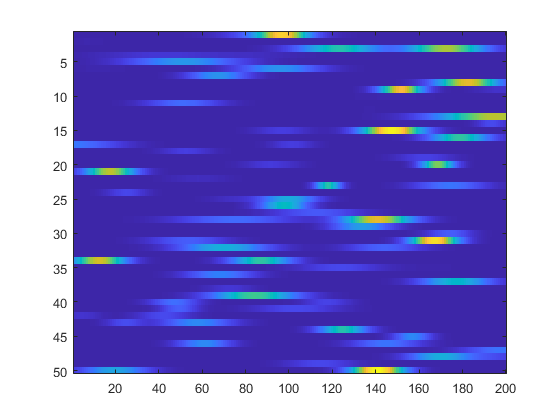

prob_2field=0.5; %This is the probability that a cell will have 2 fields instead of one

bins=1:track_length;
true_firing_rate=zeros(n_cells,track_length);

for i=1:n_cells
    n_fields=1+(rand(1)<prob_2field);
    for j=1:n_fields
    true_firing_rate(i,:)=true_firing_rate(i,:)+pf_rate(i,j).*exp(-(bins-pf_centers(i,j)).^2/(2*pf_size(i,j)^2));
    end
end

imagesc(true_firing_rate)

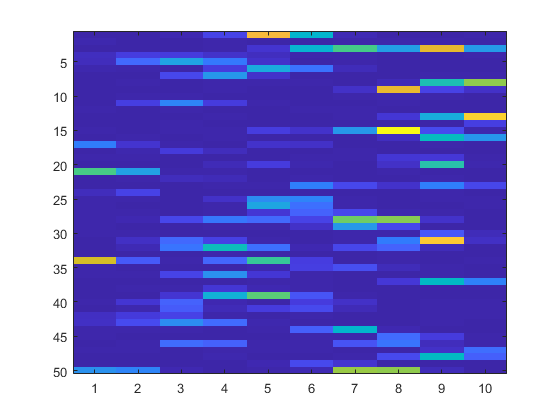


% Let's now check our estimation map

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 0.1; % the baseline noise firing rate
spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
end

% To estimate the PVs we will use bins of some cms in length 
bin_size=20; % Size in cm of bins to use for encoding
n_bins = track_length/bin_size;

estim_firing_rate=zeros(n_cells,n_bins);

% Rescale the trajectory to the new binning 
x_sampling_binned = ceil(x_sampling/(track_length/n_bins));

% Calculate the PV for every bin
for j=1:n_bins
    X_bin=find(x_sampling_binned==j);
    estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
end

imagesc(estim_firing_rate)

**Question 6: **Compare the performance of position reconstruction with different values of *prob_2field. *Why is the presence of additional fields making decoding more challenging? 

probs = [2];
euclid = 0; bayes = 0; cosine = 0; correl = 0;

for it = 1:numel(probs)
    prob_2field=probs(it); %This is the probability that a cell will have 2 fields instead of one
    
    bins=1:track_length;
    true_firing_rate=zeros(n_cells,track_length);
    
    for i=1:n_cells
        a = rand(1);
        if a>prob_2field
            n_fields = 1;
        else
            n_fields = 2;
        end
        for j=1:n_fields
            true_firing_rate(i,:)=true_firing_rate(i,:)+pf_rate(i,j).*exp(-(bins-pf_centers(i,j)).^2/(2*pf_size(i,j)^2));
        end
    end
    
    running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
    running_speed_b = chi2rnd(av_running_speed, n_runs,1); 
    
    x = [];
    for i=1:n_runs
        run_length = numel(bins) * fps / running_speed_a(i);
        run1 = linspace(0.1, numel(bins), round(run_length));
        run_length = numel(bins) * fps / running_speed_b(i);
        run2 = linspace(numel(bins), 0.1, round(run_length));
        x=cat(1,x,run1(:),run2(:));
    end
    t=(1:numel(x))./fps; 
    
    sampling_rate = 10; %This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
    t_sampling = (1:numel(t))./sampling_rate;
    x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
    noise_firing_rate = 5; % the baseline noise firing rate
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,:)=spikes_loc;
    end
    
    estim_firing_rate=zeros(n_cells,n_bins);
    
    % Rescale the trajectory to the new binning
    x_sampling_binned = ceil(x_sampling/(track_length/n_bins));
    
    % Calculate the PV for every bin
    for j=1:n_bins
        X_bin=find(x_sampling_binned==j);
        estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
    end
    
    sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
    t_sampling = (1:numel(t))./sampling_rate;
    x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
    noise_firing_rate = 5; % the baseline noise firing rate
    
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,:)=spikes_loc;
    end
    
    x_decoded_bay=zeros(size(spikes,2),1);
    x_decoded_euc=zeros(size(spikes,2),1);
    x_decoded_cor=zeros(size(spikes,2),1);
    x_decoded_cos=zeros(size(spikes,2),1);
    for t_bin=1:size(spikes,2)
        
        if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spike
            
            Post_p=NaN(size(estim_firing_rate,2),1);
            euc=NaN(size(estim_firing_rate,2),1);
            cor=NaN(size(estim_firing_rate,2),1);
            cos=NaN(size(estim_firing_rate,2),1);
            cheb=NaN(size(estim_firing_rate,2),1);
            for i=1:size(estim_firing_rate,2)
                Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate(:,i)/sampling_rate)));
                euc(i)=pdist2(estim_firing_rate(:,i)'/sum(estim_firing_rate(:,i)),spikes(:,t_bin)','euclidean');
                cor(i)=pdist2(estim_firing_rate(:,i)',spikes(:,t_bin)','correlation');
                cos(i)=pdist2(estim_firing_rate(:,i)',spikes(:,t_bin)','cosine');
                cheb(i)=pdist2(estim_firing_rate(:,i)',spikes(:,t_bin)','chebychev');
            end
            x_decoded_bay(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
            x_decoded_euc(t_bin) = find(euc==nanmin(euc),1,'first');
            x_decoded_cor(t_bin) = find(cor==nanmin(cor),1,'first');
            x_decoded_cos(t_bin) = find(cos==nanmin(cos),1,'first');
            
        else
            x_decoded_bay(t_bin) = NaN;
            x_decoded_euc(t_bin) = NaN;
            x_decoded_cor(t_bin) = NaN;
            x_decoded_cos(t_bin) = NaN;
        end
    end
    
    bayes(it) = nanmedian(sqrt(((x_sampling-x_decoded_bay*bin_size).^2)));
    euclid(it) = nanmedian(sqrt(((x_sampling-x_decoded_euc*bin_size).^2)));
    correl(it) = nanmedian(sqrt(((x_sampling-x_decoded_cor*bin_size).^2)));
    cosine(it) = nanmedian(sqrt(((x_sampling-x_decoded_cos*bin_size).^2)));
end

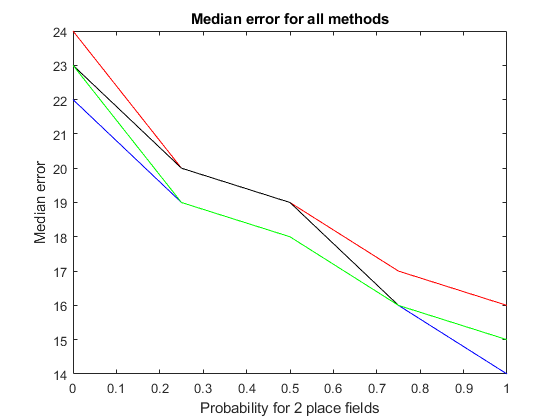

plot(probs,bayes,'b')
hold on
plot(probs,euclid,'r')
plot(probs,correl,'k')
plot(probs,cosine,'g')
xlabel('Probability for 2 place fields')
ylabel('Median error')
title('Median error for all methods')
hold off

The median error decreases, this is odd as we expect decoding to be more difficult when we have 2 place fields instead of just 1. I don't have the time to fix this, but I'll describe below what I should expect to happen.

Decoding should is more challenging, because we essentially have more 'noise' in our data. Either one of the locations is picked as the place-field location, but since the other location also produces spikes, these other spikes might lead to a different decoded signal and thus act as 'noise'. As noise means that we can less-well decode our location, we would then also expect our decoding performance to drop. We would thus expect our median error to increase with an increasing probability of 2 place fields per cell.

Notice that we here only decode one location, this would be different if we would have to decode two locations whenever there are two place-cells, namely then we would be more likely to make a mistake overall as we have to decode more. This would also lead to decreased decoding performance. This is not incorporated here, but should be considered in real analysis.

**Question 7: **Is Bayesian decoding more or less affected than similarity-based methods? 

Overall, we do not see much difference between the moethods, but I'd expect the bayesian method to be more robust, as explained below.

We cannot infer from our results, but we would expect the bayesian strategy to be less-affected since it matches probabilities and not just frequency of spikes. It therefore should be more robust against such noise, which adds another place of higher probability. With increasing probability, the distance measures should perform worse. The 'noise' we induce with our increasing probability of 2 place fields will namely also mean that we have more chance of wrongly assigning one place to a specific pattern.

**2D ENVIRONMENT**

Similarly we can ask what effect has increasing the dimensionality of the environment, by for example using a square box instead of a linear track to simulate the movements of the mouse. You can use the following code to simulate the activity of a group of place cells in a 2D environment.

We start as usual by defining the relevant variables: 

clear all;
room_size = 100; % the side of our square environment (eg in centimeter)
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 20; % how many cells we are recording
pf_centers = [rand(n_cells,1) * room_size rand(n_cells,1) * room_size ]; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
pf_size = gamrnd(10,1, n_cells,1); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,1); % the peak firing rate for each cell, drawn from an exponential distribution

Let's build place fields in 2D

bins=1:room_size;
true_firing_rate=zeros(room_size*room_size,n_cells);

[bin_Y,bin_X]=meshgrid(bins);

bin_Y=bin_Y(:);
bin_X=bin_X(:);
% Place Fields are two-dimensional symmetric Gaussians 
for i=1:n_cells
    true_firing_rate(:,i)=pf_rate(i).*exp(-((bin_Y-pf_centers(i,2)).^2 ...
        +(bin_X-pf_centers(i,1)).^2)/(2*pf_size(i)^2));
end

true_firing_rate = reshape(true_firing_rate,room_size,room_size,n_cells);

We can use a "slider" (Control, above) to visualize the 2D place field of different cells. 

i=1

i = 1

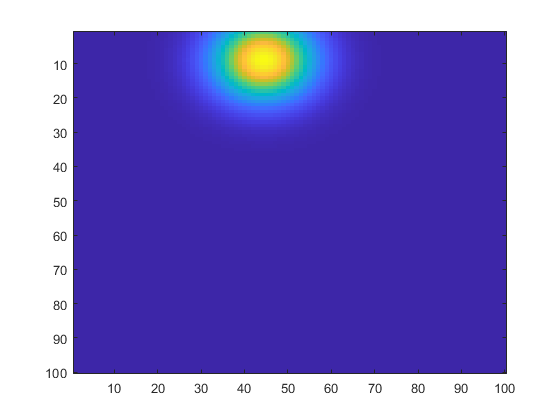

imagesc(true_firing_rate(:,:,i))

Here we build a 2-dimensional trajectory:

run_length = 500; % In seconds
av_running_speed = 10;% the average running speed (in cm/s)
fps = 10; % the number of "video frames" per second 
run_bins = run_length*fps;

running_speed = chi2rnd(av_running_speed, run_bins,1); % running speed in the two directions

% Random initial position and direction 
xy_pos = zeros(run_bins,2);
xy_pos(1,:) = [rand(1) rand(1)]*room_size;

direction = rand(1)*2*pi;

for t=2:run_bins
    direction = direction + rand(1)*pi/4 - pi/8; % Direction changes smoothly in time
    xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)/fps*[cos(direction) sin(direction)];
% Check if the new position is within the box boundaries, otherwise pick anothe one    
while(sum(xy_pos(t,:)>room_size) || sum(xy_pos(t,:)<0))
    direction = rand(1)*2*pi;
    xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)*[cos(direction) sin(direction)];
end
    

end
t=(1:size(xy_pos,1))./fps;  



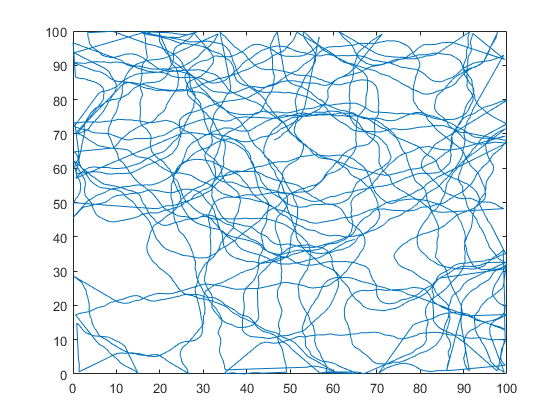

plot(xy_pos(:,1),xy_pos(:,2))

And as before we can generate spiking activity along the trajectory.

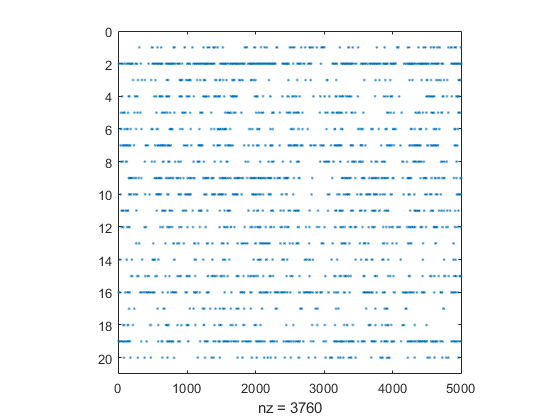

sampling_rate = 10;
t_sampling = (1:numel(t))./sampling_rate;
xy_sampling = zeros(size(xy_pos));
xy_sampling(:,1) = ceil(interp1(t, xy_pos(:,1),t_sampling,'linear','extrap'))';
xy_sampling(:,2) = ceil(interp1(t, xy_pos(:,2),t_sampling,'linear','extrap'))';

noise_firing_rate = 0.1; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    for t=1:numel(t_sampling)
    inst_rate = true_firing_rate(xy_sampling(t,2),xy_sampling(t,1),i) + noise_firing_rate;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,t)=spikes_loc;
    end
end

spy(spikes)
axis square

And finally we can estimate the neural representation from the "recorded" activity, equivalently to what we did before, just with an additional dimension.  

bin_size=10; % Size in cm of bins to use for decoding
n_bins = room_size/bin_size;

estim_firing_rate=zeros(n_bins,n_bins,n_cells);

xy_sampling_binned = ceil(xy_sampling/(bin_size));

for jx=1:n_bins
    for jy=1:n_bins
        XY_bin=find(xy_sampling_binned(:,1)==jx & xy_sampling_binned(:,2)==jy);
        estim_firing_rate(jy,jx,:)=sum(spikes(:,XY_bin),2)*sampling_rate./(numel(XY_bin));
    end
end

i=4

i = 4

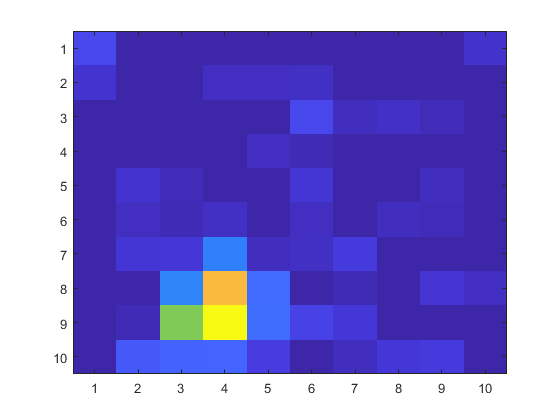

imagesc(estim_firing_rate(:,:,i))

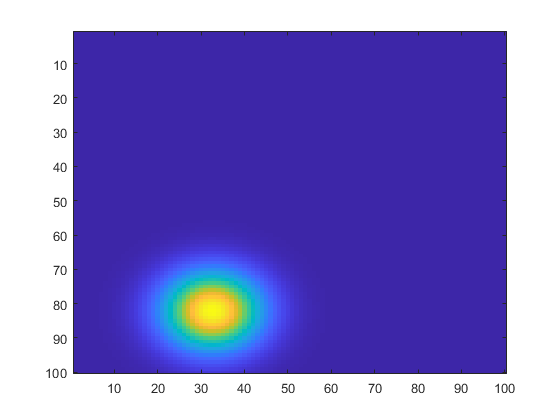

imagesc(true_firing_rate(:,:,i))

**Question 8: **The addition of an extra-dimension has a major effect on the computational complexity of both estimating PVs representing different locations and on the precision with wich one can decode position. Given equivalent amount of noise and place field properties, find how many cells are approximately required to acheive the same decoding precision of the linear track (you can use an arbitrarily long trajectory).

First we should find out what the decoding precision in this 2D case is.

% We first reshape our estimated firing rate in order to be able to compare
% it to spikes
estim_firing_rate_reshaped = reshape(estim_firing_rate,n_bins*n_bins,n_cells);

xy_decoded=zeros(size(spikes,2),2);
for t_bin=1:size(spikes,2)
    if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
        Post_p=NaN(size(estim_firing_rate,2),1);
        for i=1:size(estim_firing_rate_reshaped,1)
            Post_p(i)=sum(log(poisspdf(spikes(:,t_bin)',estim_firing_rate_reshaped(i,:)/sampling_rate)));
        end
        % We then find the optimal position and get the bin numbers to which this
        % position it belongs
        opt = find(Post_p==nanmax(Post_p),1,'first');
        % Check if opt is not 100, otherwise our strategy doesn't work,
        % easy fix through if statement
        if opt < 100
            opt = str2double(regexp(num2str(opt),'\d','match'));
            opt(1) = opt(1) + 1;
        else
            opt = [10 10];
        end
        xy_decoded(t_bin,:) = opt;
    else
        xy_decoded(t_bin,:) = NaN;
    end
end
meds = mean(nanmedian(sqrt(((xy_sampling-xy_decoded*n_bins).^2))))

meds = 11.5000

Okay, so our median error is around 11 in this case (with noise =0.1, and a run time of 500 sec). We know that, on a 1D track, we have a nanmedian error of around 6 with 100 cells and a noise of 0.1 (same place field properties). Let's now check if we can get similar results on the 2D track by iterating over numbers of cells.

cells = [50,75,100,125,150,175,200];
meds = zeros(numel(cells),1);

for it = 1:numel(cells)
    n_cells = cells(it) % how many cells we are recording
    room_size = 100; % the side of our square environment (eg in centimeter)
    average_firing_rate = 5; % the peak firing rate, averaged across the population 
    pf_centers = [rand(n_cells,1) * room_size rand(n_cells,1) * room_size ]; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
    pf_size = gamrnd(10,1, n_cells,1); % the size (width) of the place fields, drawn randomly from a gamma distribution 
    pf_rate = exprnd(average_firing_rate,n_cells,1); % the peak firing rate for each cell, drawn from an exponential distribution
    
    bins=1:room_size;
    true_firing_rate=zeros(room_size*room_size,n_cells);
    
    [bin_Y,bin_X]=meshgrid(bins);
    
    bin_Y=bin_Y(:);
    bin_X=bin_X(:);
    % Place Fields are two-dimensional symmetric Gaussians 
    for i=1:n_cells
        true_firing_rate(:,i)=pf_rate(i).*exp(-((bin_Y-pf_centers(i,2)).^2 ...
            +(bin_X-pf_centers(i,1)).^2)/(2*pf_size(i)^2));
    end
    
    true_firing_rate = reshape(true_firing_rate,room_size,room_size,n_cells);
    
    run_length = 500; % In seconds
    av_running_speed = 10;% the average running speed (in cm/s)
    fps = 10; % the number of "video frames" per second 
    run_bins = run_length*fps;
    
    running_speed = chi2rnd(av_running_speed, run_bins,1); % running speed in the two directions
    
    % Random initial position and direction 
    xy_pos = zeros(run_bins,2);
    xy_pos(1,:) = [rand(1) rand(1)]*room_size;
    
    direction = rand(1)*2*pi;
    
    for t=2:run_bins
        direction = direction + rand(1)*pi/4 - pi/8; % Direction changes smoothly in time
        xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)/fps*[cos(direction) sin(direction)];
    % Check if the new position is within the box boundaries, otherwise pick anothe one    
    while(sum(xy_pos(t,:)>room_size) || sum(xy_pos(t,:)<0))
        direction = rand(1)*2*pi;
        xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)*[cos(direction) sin(direction)];
    end
        
    
    end
    t=(1:size(xy_pos,1))./fps;  
    
    sampling_rate = 10;
    t_sampling = (1:numel(t))./sampling_rate;
    xy_sampling = zeros(size(xy_pos));
    xy_sampling(:,1) = ceil(interp1(t, xy_pos(:,1),t_sampling,'linear','extrap'))';
    xy_sampling(:,2) = ceil(interp1(t, xy_pos(:,2),t_sampling,'linear','extrap'))';
    
    noise_firing_rate = 0.1; % the baseline noise firing rate
    
    spikes = zeros(n_cells,numel(t_sampling));
    
    for i=1:n_cells
        for t=1:numel(t_sampling)
        inst_rate = true_firing_rate(xy_sampling(t,2),xy_sampling(t,1),i) + noise_firing_rate;
        spikes_loc = poissrnd(inst_rate/sampling_rate);
        spikes(i,t)=spikes_loc;
        end
    end
    
    bin_size=10; % Size in cm of bins to use for decoding
    n_bins = room_size/bin_size;
    
    estim_firing_rate=zeros(n_bins,n_bins,n_cells);
    
    xy_sampling_binned = ceil(xy_sampling/(bin_size));
    
    for jx=1:n_bins
        for jy=1:n_bins
            XY_bin=find(xy_sampling_binned(:,1)==jx & xy_sampling_binned(:,2)==jy);
            estim_firing_rate(jy,jx,:)=sum(spikes(:,XY_bin),2)*sampling_rate./(numel(XY_bin));
        end
    end
        
    % We first reshape our estimated firing rate in order to be able to compare
    % it to spikes
    estim_firing_rate_reshaped = reshape(estim_firing_rate,n_bins*n_bins,n_cells);
    
    xy_decoded=zeros(size(spikes,2),2);
    for t_bin=1:size(spikes,2)
        if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
            Post_p=NaN(size(estim_firing_rate,2),1);
            for i=1:size(estim_firing_rate_reshaped,1)
                Post_p(i)=sum(log(poisspdf(spikes(:,t_bin)',estim_firing_rate_reshaped(i,:)/sampling_rate)));
            end
            % We then find the optimal position and get the bin numbers to which this
            % position it belongs
            opt = find(Post_p==nanmax(Post_p),1,'first');
            % Check if opt is not 100, otherwise our strategy doesn't work,
            % easy fix through if statement
            if opt < 100
                opt = str2double(regexp(num2str(opt),'\d','match')); % decompose value
                opt(1) = opt(1) + 1;
            else
                opt = [10 10];
            end
            xy_decoded(t_bin,:) = opt;
        else
            xy_decoded(t_bin,:) = NaN;
        end
    end
    meds(it) = mean(nanmedian(sqrt(((xy_sampling-xy_decoded*n_bins).^2))));   
end

n_cells = 50

n_cells = 75

n_cells = 100

n_cells = 125

n_cells = 150

n_cells = 175

n_cells = 200

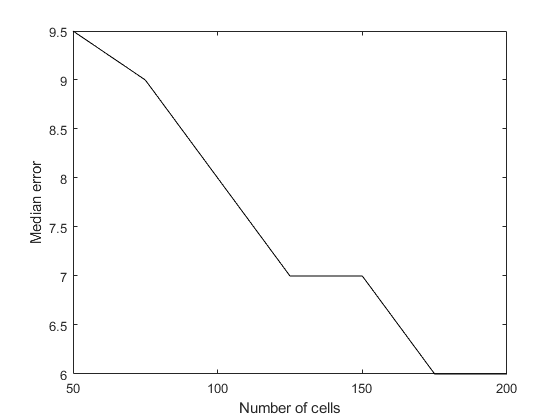

plot(cells,meds,'k')
xlabel('Number of cells')
ylabel('Median error')

In general, we see that we need less place-cells on a linear track to correctly decode a position, this is fairly logical as less locations need to be represented. For the 2D case, we see that we need about 175 cells for it to reach a similar median error as the 1D case. This means that we need almost double the amount of cells! Of course this is very logical, since it should be more difficult to decode a 2D position than a 1D position. There is not only the difficulty in predicting in more space, also there is overall more noise due to this added amount of space. 2D positional decoding is thus a lot more difficult, however I'd expect 3D to be even more difficult!

**Question 9: **Having the animal thoroughly covering the entire environment is also an issue when in 2-dimensions. Using spatial binning of different size, estimate how long the trajectory should be so that each bin is visited at least twice.  

% So what we do is to simulate for a given time, keeping track of all the
% places where we've been in a list. If we have visited all bins 2 times,
% we stop the loop and we note the time at which we did so.

clear all;

t_ests = zeros(1,20);

for it = 1:numel(t_ests)
    room_size = 100; % the side of our square environment (eg in centimeter)
    average_firing_rate = 5; % the peak firing rate, averaged across the population 
    n_cells = 100; % how many cells we are recording
    
    run_length = 5000; % In seconds
    av_running_speed = 10;% the average running speed (in cm/s)
    fps = 1; % the number of "video frames" per second 
    run_bins = run_length*fps;
    
    bin_size=10; % Size in cm of bins to use for decoding
    n_bins = room_size/bin_size;
    
    running_speed = chi2rnd(av_running_speed, run_bins,1); % running speed in the two directions
    
    % Random initial position and direction 
    xy_pos = zeros(run_bins,2);
    xy_pos(1,:) = [rand(1) rand(1)]*room_size;
    
    direction = rand(1)*2*pi;
    
    binlist = zeros(run_bins,2);
    
    bincount = [0 0];
    
    for t=2:run_bins
        direction = direction + rand(1)*pi/4 - pi/8; % Direction changes smoothly in time
        xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)/fps*[cos(direction) sin(direction)];
        % Check if the new position is within the box boundaries, otherwise pick anothe one    
        while(sum(xy_pos(t,:)>room_size) || sum(xy_pos(t,:)<0))
            direction = rand(1)*2*pi;
            xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)*[cos(direction) sin(direction)];
        end
        
        % Keep count of where we are
        cur_bin = ceil(xy_pos(t,:)/n_bins);
        if bincount == [0 0] | cur_bin ~= bincount % If we are in a new bin, note down
            bincount = cur_bin;
            binlist(t,:) = cur_bin;
        end
        
        % Check if we have bin to all bins 2 times by counting
        [Au,~,ic] = unique(binlist, 'stable', 'rows');
        tally = accumarray(ic, 1);
        if all(tally>=2) && numel(tally) == n_bins^2+1
            t_est = t/fps;
            break
        end
       
    end
    t_ests(it) = t_est;
end

average_time = mean(t_ests)

average_time = 2.3778e+03

std_time = std(t_ests)

std_time = 446.0631

It seems that, with a binning of 10 cm^2 , we need about 2778+-446 seconds (~45 minutes) for the mouse to have been in all the bins. This is a very long time indeed! From our simulation, we can thus deduce that it is a very difficult task to be sure the mouse has reached all bins enough times.

## REACTIVATIONS AND REPLAY

The use of decoding methods is not limited to measure the amount of information that a neural population carries about a specific set of stimuli, or to predict what stimulus is present at a given time. It is extremely useful to interpret the content of neural activity when no stimulus is present and such activity is spontaneously generated by the network and is not elicited by a specific stimulus. 

In the case of the hippocampus it has now been extensively observed that during rest periods (either while the animal is standing still, waiting somewhere, or while it is sleeping) place cells reactivate specific patterns of activity corresponding to sequences of locations in the environment. This phenomenon, called "replay" is thought to be critical for the formation of memory, for the acquisition of novel knowledge and for the reorganization of different sorts of information in the brain (You can read [this](https://www.sciencedirect.com/science/article/pii/S0166223610000172?via%3Dihub) for an overview on this vast and ebullient field of research).    

Here we want simulate the occurrence of such reactivation events. Some of them will actually contain sequences, that is, the neural activity will represents a series of locations in the order they appear on the linear track. Other reactivation events will instead contain activity representing locations of the linear track, but these locations will be randomly drawn, so they will present no clear ordering. 

Let's generate these events:   

% First we again reinstate our parameters on the 1D track

clear all;
track_length = 200; % the length of our linear track (eg in centimeter)
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 100; % how many cells we are recording
pf_centers = rand(n_cells,1) * track_length; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
pf_size = gamrnd(10,1, n_cells,1); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,1); % the peak firing rate for each cell, drawn from an exponential distribution

bins=1:track_length;
true_firing_rate=zeros(n_cells,track_length);
%Place Fields have a Gaussian shape
for i=1:n_cells
    true_firing_rate(i,:)=pf_rate(i).*exp(-(bins-pf_centers(i)).^2/(2*pf_size(i)^2));
end

n_runs = 20; 
av_running_speed = 10;% the average running speed (in cm/s)
fps = 10; % the number of "video frames" per second 
running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
running_speed_b = chi2rnd(av_running_speed, n_runs,1); 

x = [];
for i=1:n_runs
    run_length = numel(bins) * fps / running_speed_a(i);
    run1 = linspace(0.1, numel(bins), round(run_length));
    run_length = numel(bins) * fps / running_speed_b(i);
    run2 = linspace(numel(bins), 0.1, round(run_length));
    x=cat(1,x,run1(:),run2(:));
end
t=(1:numel(x))./fps; 

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 0.1; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
end

% To estimate the PVs we will use bins of some cms in length 
bin_size=4; % Size in cm of bins to use for encoding
n_bins = track_length/bin_size;

estim_firing_rate=zeros(n_cells,n_bins);

% Rescale the trajectory to the new binning 
x_sampling_binned = ceil(x_sampling/(track_length/n_bins));

% Calculate the PV for every bin
for j=1:n_bins
    X_bin=find(x_sampling_binned==j);
    estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
end

spikes_react_events = cell(200,1); %200 reactivation events

for event=1:200

    sampling_rate = 100;
    
    t_react = 1:100;
    
    noise_x_react=5; % Noise in the reactivation of the sequence
    noise_t_react=5; % Noise in the timing of the spikes 
    
    if(event<=100)
        % Generate "real" sequences for the first half of events
        x_start = rand(1)*track_length; % Starting point
        x_end = rand(1)*track_length;% Ending point
        x_react = ceil(linspace(x_start,x_end,100)+randn(1,100)*noise_x_react)';
    elseif(event>100)
        % Pick locations randomly for the second half 
        x_react = ceil(rand(100,1)*track_length);
    end
    
    x_react(x_react<1)=1;
    x_react(x_react>track_length)=track_length;
    
    noise_firing_rate = 0.1; % the baseline noise firing rate
    
    spikes_react = zeros(n_cells,numel(t_react));
    
    % Generate spikes according to the location being reactivated in this event
    for i=1:n_cells
        inst_rate = true_firing_rate(i,x_react) + randn(1,numel(x_react))*noise_firing_rate;
        inst_rate(inst_rate<0) = 0;
        spikes_loc = find(poissrnd(inst_rate/sampling_rate));
        spikes_loc = spikes_loc + round(randn(numel(spikes_loc),1)*noise_t_react);
        spikes_loc = spikes_loc(ismember(spikes_loc,1:100));
        spikes_react(i,spikes_loc)=1;
        
    end
    % Put the data in a cell-array
    spikes_react_events{event} = spikes_react;

end


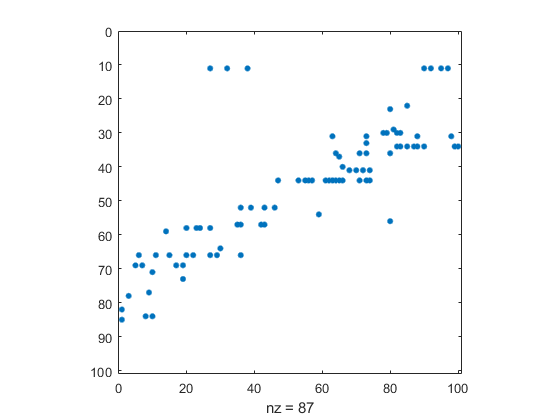

% Reorder cells in terms of the position of their place field on the track 
[~,pf_order]=sort(pf_centers,'ascend');

%We can use this reordering to "visualize the reactivation"
% An example of a sequential reactivation 
Event_Spikes=spikes_react_events{2};
spy(Event_Spikes(pf_order,:))

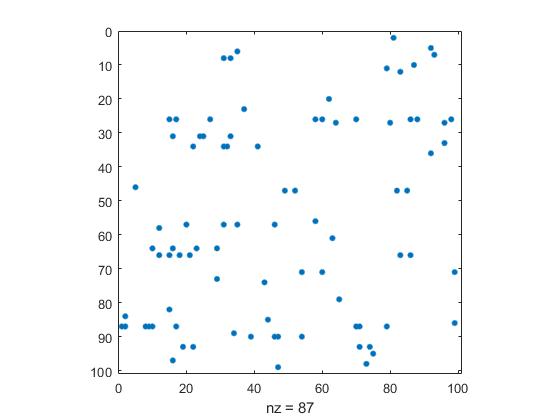


% An example of a non-sequential reactivation
Event_Spikes=spikes_react_events{102};
spy(Event_Spikes(pf_order,:))

We will now decode the activity contained in these events and try to detect sequential activation looking at the correlation between time within the event and decoded position.  

t_resize = 10; % We use spikes from multiple time windows for the decoding

xdec = zeros(200,10);

reactivation_slope = zeros(200,1);
for event=1:200

        spikes_react = spikes_react_events{event};
        
        spikes_react_sampled = zeros(n_cells,size(spikes_react,2)/t_resize);
    
    % We generate a new spike matrix with the re-sized window
    for t_r=1:100/t_resize
        spikes_react_sampled(:,t_r) = sum(spikes_react(:,(t_r-1)*10+1:(t_r)*10),2);
    end
    
    %And then we perform the same Bayesian decoding as before 
    x_decoded=zeros(size(spikes_react_sampled,2),1);
    for t_bin=1:size(spikes_react_sampled,2)
        
        if(sum(spikes_react_sampled(:,t_bin),1)>0) % Check if the time window contains spikes
        
            Post_p=NaN(size(estim_firing_rate,2),1);
            for i=1:size(estim_firing_rate,2)
                
                Post_p(i)=sum(log(poisspdf(spikes_react_sampled(:,t_bin),estim_firing_rate(:,i)/sampling_rate*t_resize)));
               
            end
        
            x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
        else
            x_decoded(t_bin) = NaN;   
        end
        xdec(event,t_bin) = x_decoded(t_bin);
    end
    
    
    % Linear fit of 
    %beta = polyfit(1:numel(x_decoded),x_decoded',1);
    [rr,pp] = corr((1:numel(x_decoded))',x_decoded);
    
    reactivation_slope(event) = pp;%beta(1);
end

**Question 10: **Can you estimate the amount of times this criterion would label as a sequence a non-sequential event?  

We know that the first 100 events must be sequential, for these events, the reactivation slope should thus be very low as compared to non-sequential events. We should thus define a threshold for the reactivation slope, above which we call an event non-sequential. Looking at our values, I'd way 0.05 is a good number for this threshold (but it's debatable)

threshold = 0.05;
count = 0;
for event=1:100 % go over the first, sequential, events
    if reactivation_slope(event) > threshold
        count = count + 1;
    end
end
count

count = 18

So we have 18 false negatives in our data. Now we can also look at the false positives

count = 0;
for event=100:200 % go over the first, sequential, events
    if reactivation_slope(event) < threshold
        count = count + 1;
    end
end
count

count = 12

So we have 12 false positives in our data.

This means that this criterion is relatively good, but not perfect. Also, as noted, the choice of threshold is very important for the results. If we take a smaller threshold, we get more false negatives, but less false positives and if we take a larger threshold, we get less false negatives and more false positives. There is thus a tradeoff and this should be considered.

**Question 11: **Can you think of a better way to define a sequence?

In the above, a sequence would be defined by the slope it makes through the sequence and subsequently setting a threshold when we then consider something a sequence and when not. This method seems to work relatively well, but there sure are better ways.

The current setup just looks if the replay follows a standard linear dependency in time, however, this measure breaks down when replay stays at a certain location for a longer time, thereby 'ruining' the slope. The same can be said for when the replay skips a location, which might occur. These 'outliers' can have some serious consequences for our measure and are, for example, also heavily dependent on the time bins in which we resize time. In this sense, I think it is better to look for a similar measure, but considering such 'jumps' or 'stops' as well. The direct slope is thus not a good indicator.

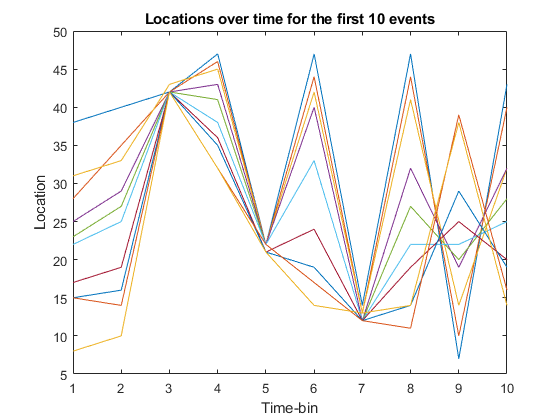

plot(xdec(1:10,:))
xlabel("Time-bin")
ylabel("Location")
title("Locations over time for the first 10 events")

In this plot we see that, indeed, there is still quite some variability in the location per time-bin for a given event sequence. This means that a sloope estimation will not be the greatest tool at estimating whether or not something is a sequence.

A better way might be to take the difference between the location at each time-bin and then to threshold that, but even that might not be very robust.

Perhaps you could also use a polynomial to test the correlation against.